## Partie I


fichier = load("EteV35Nu10.txt");
Demande = fichier(:,2);
Peol = fichier(:,3);
Ppv = fichier(:,4);
Prix = fichier(:,5);

% données du problème 
Qh2ini = 10; %MWh
Ppacmax = 15; %MW
Pelecmin = 5; %MW
Pelecmax = 30; %MW 
Relec = 0.6;
Rpac = 0.8;
Celec = 1;
Cpac = -4;
Preste = Demande - Peol - Ppv;
Qh2jour = 0;
N=24;

fobj = @(x) sum(x)+(Preste +x(1:N)'.*x(N+1:2*N)')'*Prix;

x0 = [(Pelecmax)/2*ones(1,N) ones(1,N)];
lb = [Pelecmin*ones(1,N) zeros(1,N)];
ub = [Pelecmax*ones(1,N) ones(1,N)];
intcon = (N+1):N*2;
fval_tot = [];
Qh2 = [1:10:100];
fobj2 = @(x) sum(x)+(Preste +x(1:N)')'*Prix;
lb2 = zeros(1,N);
ub2 = Pelecmax*ones(1,N);
x02 = ub2/2;
fval_tot2 = [];
Qh2 = [1:10:100];

for j = 1:10
    probleme = createOptimProblem('fmincon','x0',x02,'objective',fobj2,'lb',lb2,'ub',ub2,'nonlcon',@(x)fun_contrainte2(x, Relec, Qh2,N,j, Pelecmin));
    [x2,fval2,exitflag2,output,solutions]=run(GlobalSearch,probleme);
    fval_tot2 = [fval_tot2 fval2];
    
    [x,fval,exitflag] = ga(fobj,2*N,[],[],[],[],lb,ub,@(x) fun_contrainte(x, Relec, Qh2,N,j),intcon);
    fval_tot = [fval_tot fval];
end

No feasible solution found.

GlobalSearch called the local solver 17 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


No feasible solution found.

GlobalSearch called the local solver 25 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


No feasible solution found.

GlobalSearch called the local solver 24 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


No feasible solution found.

GlobalSearch called the local solver 28 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


No feasible solution found.

GlobalSearch called the local solver 24 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


No feasible solution found.

GlobalSearch called the local solver 22 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


No feasible solution found.

GlobalSearch called the local solver 27 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


No feasible solution found.

GlobalSearch called the local solver 22 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


No feasible solution found.

GlobalSearch called the local solver 28 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


No feasible solution found.

GlobalSearch called the local solver 28 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


### Affichage des résultats

fprintf("Convergence pour GA")

Convergence pour GA

disp(exitflag)

     1



fprintf("Pelec pour GA")

Pelec pour GA

disp(x(1:24))

  Columns 1 through 16

    5.1012    5.0006   29.8595   29.9916   27.2670    5.0005   29.4308    5.0013    5.0006    5.0158    5.0002    5.0002    5.0027    5.0059    5.0145    5.0002

  Columns 17 through 24

    5.0001    5.0017    5.0005    5.0007    5.0135    5.0012    5.0008    5.0516



fprintf("Onelec")

Onelec

disp(x(25:48))

     1     0     1     1     1     0     1     0     1     0     0     1     0     0     0     1     1     0     1     0     1     0     0     0



fprintf("Somme gagnée sur la journée pour GA")

Somme gagnée sur la journée pour GA

disp(-fval)

 -451.6981




fprintf("Convergence pour GS")

Convergence pour GS

disp(exitflag2)

    -2



fprintf("Pelec pour GS")

Pelec pour GS

disp(x2)

  Columns 1 through 16

    0.1412    9.2385   29.8534   29.8846   29.8996   29.8277   22.0218    0.0357    0.0340    0.0281    0.0304    0.0317    0.0207    0.0307    0.0307    0.0324

  Columns 17 through 24

    0.0352    0.0292    0.0474    0.0365    0.0650    0.0370    0.0759    0.2135



fprintf("Somme gagnée sur la journée pour GS")

Somme gagnée sur la journée pour GS

disp(-fval2)

 -276.0382



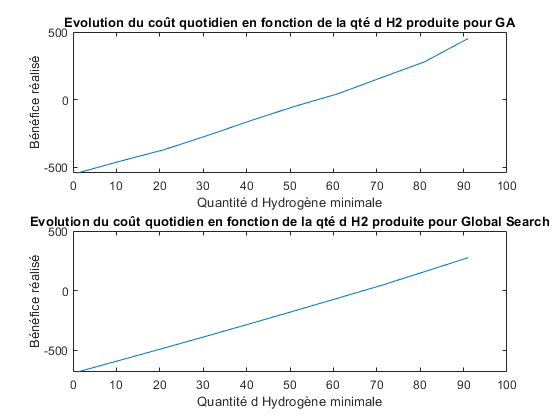


subplot(211)
plot(Qh2,fval_tot)
xlabel ('Quantité d Hydrogène minimale')
ylabel('Bénéfice réalisé')
title('Evolution du coût quotidien en fonction de la qté d H2 produite pour GA')

subplot(212)
plot(Qh2,fval_tot2)
xlabel ('Quantité d Hydrogène minimale')
ylabel('Bénéfice réalisé')
title('Evolution du coût quotidien en fonction de la qté d H2 produite pour Global Search')

#### Analyse de la performance des algorithmes : 

tic
for k = 1:10
    probleme = createOptimProblem('fmincon','x0',x02,'objective',fobj2,'lb',lb2,'ub',ub2,'nonlcon',@(x)fun_contrainte2(x, Relec, Qh2,N,k, Pelecmin));
    [x2,fval2,exitflag2,output,solutions]=run(GlobalSearch,probleme);
    fval_tot2 = [fval_tot2 fval2];
end

No feasible solution found.

GlobalSearch called the local solver 23 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).

No feasible solution found.

GlobalSearch called the local solver 24 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).

No feasible solution found.

GlobalSearch called the local solver 19 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).

No feasible solution found.

GlobalSearch called the local solver 21 times and did not find a point that satisfies
the constraints within the local solver constraint tolerance (problem.options.ConstraintTolerance).

No feasible solution found.

GlobalSearch called the local solver 28 times and did not find a point that satisfies
the constraints withi

toc

Elapsed time is 36.596411 seconds.



tic
for j = 1:10
    [x,fval,exitflag] = ga(fobj,2*N,[],[],[],[],lb,ub,@(x) fun_contrainte(x, Relec, Qh2,N,j),intcon);
    fval_tot = [fval_tot fval];
end

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less th

toc

Elapsed time is 13.240784 seconds.


fprintf('Pour un même travail, GA est environ 2,5 fois meilleur en terme de temps que GS')

Pour un même travail, GA est environ 2,5 fois meilleur en terme de temps que GS

## Partie II

fichier2 = load("AutonV50Nu40.txt");
Demande2 = fichier2(:,2)';
Peol2 = fichier2(:,3)';
Ppv2 = fichier2(:,4)';
Prix2 = fichier2(:,5)';
Preste2 = Demande2 - Peol2 - Ppv2;
N=24;
QH2max = 30;

Aeq2 = [];
beq2 = [];
Aineq2 = [ones(1,N)*Relec , zeros(1,N);
         -ones(1,N)*Relec , ones(1,N)/Rpac];
bineq2 = [QH2max ; QH2max];



FOBJ = @(x) [ sum(x(1,N+1:2*N))/Rpac - sum(x(1,1:N))*Relec , (x(1,1:N) + Preste2 - x(1,N+1:2*N))*Prix + Celec*sum(x(1,1:N)) + Cpac*sum(x(1,N+1:2*N))];
lb = zeros(1,2*N);
ub = [Pelecmax*ones(1,N) Ppacmax*ones(1,N)];
nonlcon=[];
n_points = 10;
n_pop = 100;

options = optimoptions('gamultiobj');
options.PopulationSize = n_pop;
options.ParetoFraction = 0.35;


[x4,fval4,exitflag4,output4,population4,scores4] = gamultiobj(FOBJ,2*N,Aineq2,bineq2,Aeq2,beq2,lb,ub,nonlcon,options);

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


display(fval4)

fval4 =    29.9965  223.7776
  -13.8632  710.7136
  -18.1371  739.6002
    1.9202  524.1398
  -12.2589  680.4516
   -6.5123  614.0872
   -7.3829  629.3398
   27.6839  251.0647
   18.6485  353.3770
  -16.8642  726.4934


display(x4)

x4 =     1.8436    0.0000    2.7238    1.5769    0.0010    0.0000    0.0039    0.0947    1.0000    1.0594    0.0141    0.9541    0.0000    0.0000    0.4396    0.1269    0.3150    0.6074    0.0263    0.0000    0.0000    0.0142    0.8149    0.0000    0.4684    0.0156    1.9206    0.3864    0.0454    0.2500    0.0029    0.0000    0.0133   12.4486    2.5931    0.3335    1.8811    5.2496    0.0603    1.0444    0.0112    0.1094    0.7624    0.1627    1.0917    0.6385    0.0625    0.0210
    2.0533    3.9880   17.6691    1.9147   12.2960    0.1628    0.1859    0.1878    0.2112    1.5821    0.2470    1.1982    0.0043    0.3935    0.4930    0.4133    0.6298    1.6456    0.0986    0.4774    0.2526    0.9682    1.2440    0.1627    0.6151    0.8132    2.1432    0.5312    0.1389    0.2407    0.0309    0.0242    0.1004    0.4302    0.3079    0.1348    1.9660    0.4613    0.2416    1.1814    0.1997    0.2178    0.0139    0.3577    1.2988    0.7020    0.0175    0.0111
    1.8294    3.7252   17.6754   

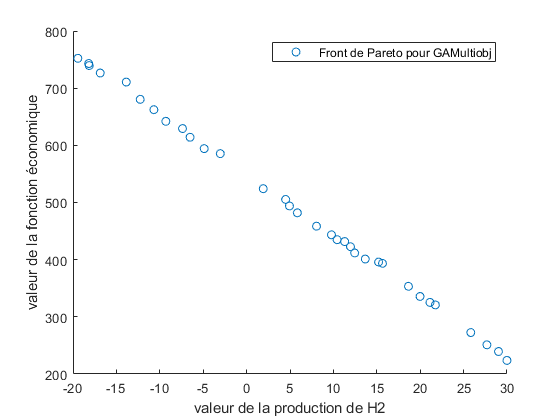


figure
scatter(fval4(:,1),fval4(:,2))
xlabel('valeur de la production de H2')
ylabel('valeur de la fonction économique')
legend('Front de Pareto pour GAMultiobj')


options = optimoptions('paretosearch');
options.ParetoSetSize = n_points;
options.MinPollFraction = 1;
On = randi(2,n_points,N) - 1;
Init = [On.*rand(n_points,N)*QH2max/Relec/24 , (1 - On).*rand(n_points,N)*QH2max*Rpac/24];
options.InitialPoints = Init;


[x5,fval5,exitflag5,output5,residuals5] = paretosearch(FOBJ,2*N,Aineq2,bineq2,Aeq2,beq2,lb,ub,nonlcon,options)


Pareto set found that satisfies the constraints. 

Optimization completed because the relative change in the volume of the Pareto set 
is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within 
'options.ConstraintTolerance'.



x5 =          0         0         0    1.3649   17.1862         0         0         0    0.7326         0    0.0906         0    0.7006         0         0         0    1.1512         0    0.5380    1.5440    0.5476         0    1.5994    1.2822    0.3252    0.2443    0.3049         0         0    0.2200    0.6125    0.1291         0    0.4370         0    0.0566   15.0000    0.2612    0.7699    0.1699         0    0.7609         0         0         0    0.9727         0         0
    1.0858    1.0946         0         0   30.0000    0.6672         0    1.5447         0         0         0         0         0    0.5419         0         0    0.0747         0         0    0.4625    0.9412         0         0         0         0         0    0.3946    0.4308         0         0    0.5348         0    0.6613    0.4076    0.1383    0.5351   15.0000         0    0.7432    0.0294         0    0.7519    0.1664         0         0    0.1516    0.8101    0.0473
    1.0858    1.0946         0   

fval5 =     9.2879  412.5442
    4.1555  453.9487
   -3.9969  537.2397
  -23.4198  772.5617
   17.1032  336.1356
    1.5996  489.4272
   21.9032  276.4716
  -17.1504  711.8772
   -9.4621  634.9942
  -13.8418  674.7059


exitflag5 = 1

output5 = struct with fields:
         iterations: 18
          funccount: 6038
             volume: 1.4533e+04
    averagedistance: 0.1546
             spread: 0.3187
      maxconstraint: 0
            message: 'Pareto set found that satisfies the constraints. ↵↵Optimization completed because the relative change in the volume of the Pareto set ↵is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within ↵'options.ConstraintTolerance'.'
           rngstate: [1×1 struct]


residuals5 = struct with fields:
         lower: [10×48 double]
         upper: [10×48 double]
       ineqlin: [10×2 double]
         eqlin: [10×0 double]
    ineqnonlin: [10×0 double]


display(fval5)

fval5 =     9.2879  412.5442
    4.1555  453.9487
   -3.9969  537.2397
  -23.4198  772.5617
   17.1032  336.1356
    1.5996  489.4272
   21.9032  276.4716
  -17.1504  711.8772
   -9.4621  634.9942
  -13.8418  674.7059


display(x5)

x5 =          0         0         0    1.3649   17.1862         0         0         0    0.7326         0    0.0906         0    0.7006         0         0         0    1.1512         0    0.5380    1.5440    0.5476         0    1.5994    1.2822    0.3252    0.2443    0.3049         0         0    0.2200    0.6125    0.1291         0    0.4370         0    0.0566   15.0000    0.2612    0.7699    0.1699         0    0.7609         0         0         0    0.9727         0         0
    1.0858    1.0946         0         0   30.0000    0.6672         0    1.5447         0         0         0         0         0    0.5419         0         0    0.0747         0         0    0.4625    0.9412         0         0         0         0         0    0.3946    0.4308         0         0    0.5348         0    0.6613    0.4076    0.1383    0.5351   15.0000         0    0.7432    0.0294         0    0.7519    0.1664         0         0    0.1516    0.8101    0.0473
    1.0858    1.0946         0   

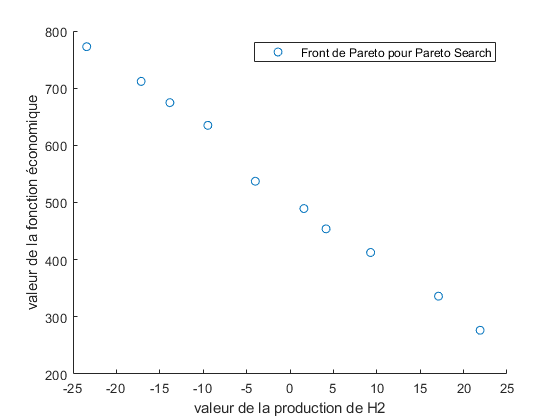


figure
scatter(fval5(:,1),fval5(:,2))
xlabel('valeur de la production de H2')
ylabel('valeur de la fonction économique')
legend('Front de Pareto pour Pareto Search')

function [cineq,ceq] = fun_contrainte2(x, Relec, Qh2,N,k, Pelecmin)
    cineq = -sum(x(1:N))*Relec + Qh2(k);
    ceq = [];
    for p = 1:N
        ceq = [ceq double((x(p)<0.01)||(x(p)>=Pelecmin))-1];
    end
end


function [cineq2,ceq2] = fun_contrainte(x, Relec, Qh2,N,j)
    cineq2 = [-sum(x(1:N).*x(N+1:2*N))*Relec + Qh2(j)];
    ceq2 = [];
end


function [cineq3, ceq3] = fun_contrainte3(x,N)
    cineq3 = x(1:N).*x(N+1:2*N);
    ceq3 = [];
end

